# **SCARA Manipulator: Analytic Inverse Kinematics Demonstration**

Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student 

Robotics 7752 | Ohio State University | 10/25/2022

with use of Modern Robotics by Kevin M. Lynch and Frank C. Park

**SCARA Background **

The SCARA-type robot is an architecture of form RRRP, widely used for table pick and place tasks. SCARA  stands for **Selective Compliance Articulated Robot Arm; **the arm is slightly compliant in the X-Y direction and rigid in the Z direction. 

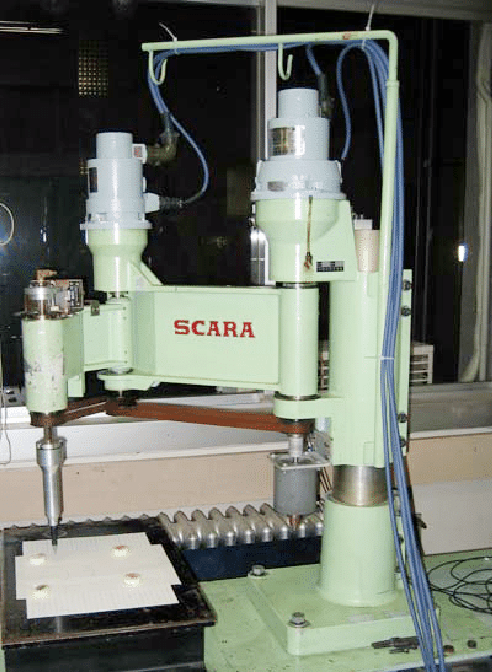

Photo from research gate 

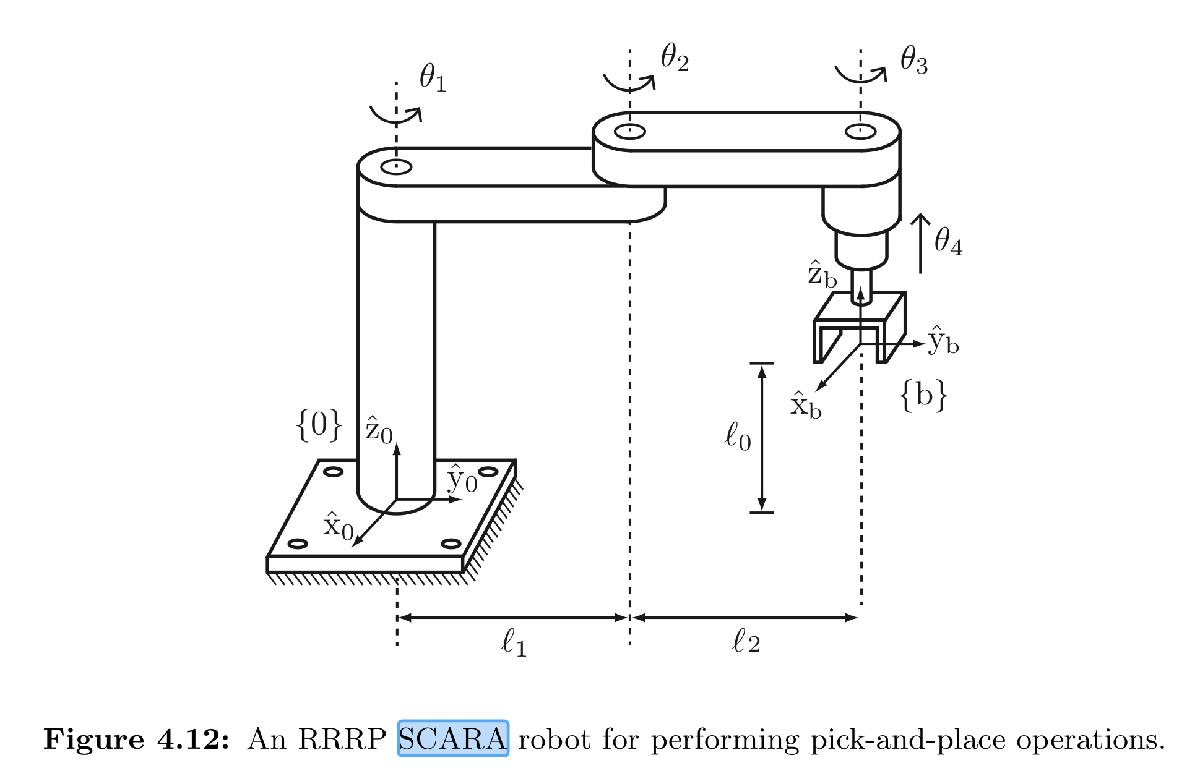

Photo from Textbook

Note that 

- links L1 and L2 with their respective joints make up a 2R planar system.

- theta 3 directly controls the orinetation of the end effector 

- theta 4 directly controls the Z Position (with L0 incorporated)

- The 2R solution differs by only the orientation  of the links with the X axis instread of y (above)

With these notes, it is relatively simple to convert the 2R planar analytic solution for inverse kinematics. 

# Beginning of SCARA Script

Variable clearing 

clc; clear; close all; 

Link Lengths

L0 = 1; L1=2; L2=2; L = [L0 L1 L2];

Home Config 

p = [0 L1+L2 L0]'; M = [[eye(3) ; 0 0 0] [p ; 1]];

Slist =      0     0     0     0
     0     0     0     0
     1     1     1     0
     0     2     4     0
     0     0     0     0
     0     0     0     1


## Analytic Inverse Kinematics

**The 2R planar solution **

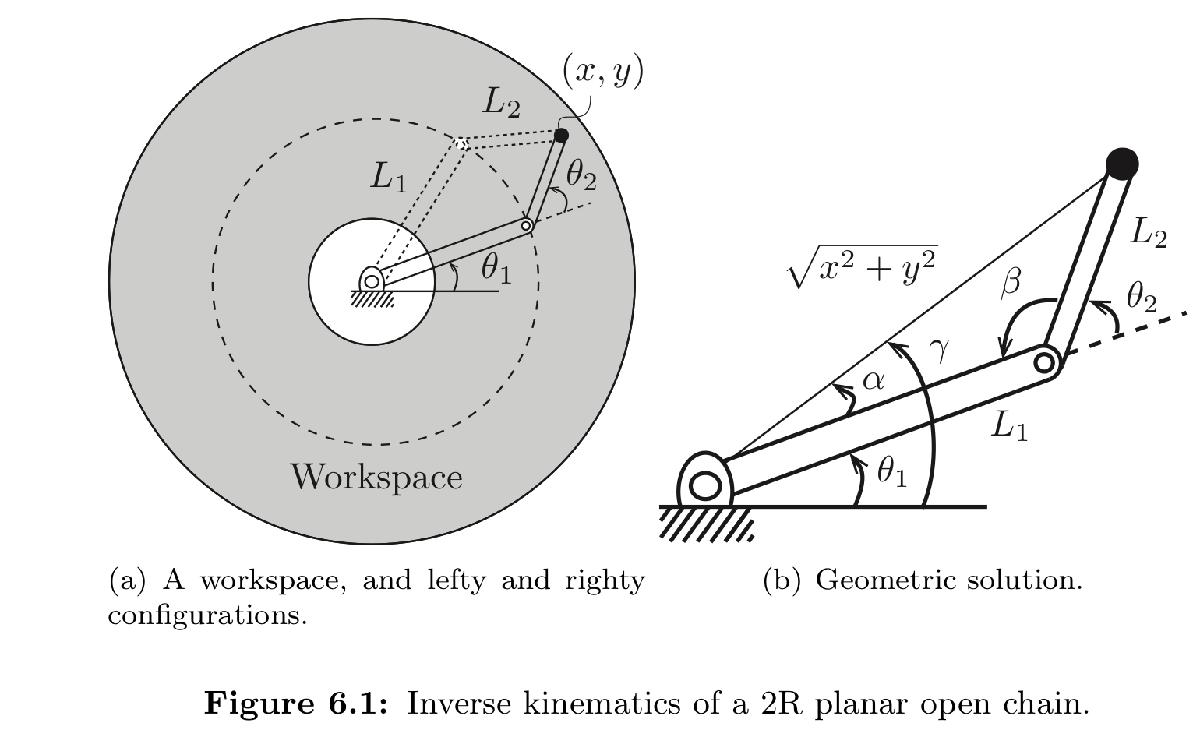

%Given T, find thetaList = [th1 th2 th3 th4]
p = [1 1 1]';
T = [[eye(3) ; 0 0 0] [p ; 1]]; %test T=M to check correctness
T=M;
%2R solution - to get th1 th2
    %Reformat - accounting for 2R solutions difference in frames
    p = T(1:3,4); 
    x = p(2);
    y = p(1);
    %Solution
    [thetasRighty thetasLefty] = IK_2R(x,y,L); %th1 and th2 
%th4 is soley dependant on z and L0
    z = T(3,4);
    th4 = z - L0;
%th3 is soley dependant on the orientation of the new end effector X axis
    y = T(2,1); x = T(1,1);
    th3 = atan2(y,x);

**The Analytic Inverse Kinematics Solutions **

thetaRighty = [thetasRighty' th3 th4]*180/pi

thetaRighty =      0     0     0     0


thetaLefty = [thetasLefty' th3 th4]*180/pi

thetaLefty =      0     0     0     0


## Numeric Inverse Kinematics Solution

# Analytic 2R Function

function [thetasRighty thetasLefty] = IK_2R(x,y,L)
    L1 = L(2); L2 = L(3);
    if (norm(x,y) < L1-L2 || norm(x,y) > L1+L2)
        disp('no solution exists')
        return
    end 
    temp = (L1^2+L2^2 - x^2 - y^2)/(2*L1*L2);
    beta = acos(temp); 
    temp = (x^2 + y^2 + L1^2 - L2^2)/(2*L1*(x^2+y^2)^.5);
    alpha = acos(temp);
    gamma = atan2(y,x);
    %The Righty Solution
    th1R = gamma - alpha;
    th2R = pi - beta;
    thetasRighty = [th1R th2R]';
    %The Lefty Solution 
    th1L = gamma + alpha;
    th2L = beta - pi;
    thetasLefty = [th1L th2L]';
end
function rot = rotz(ang) %in radians
    rot = [cos(ang) -sin(ang) 0 ; sin(ang) cos(ang) 0 ; 0 0 1];
end 